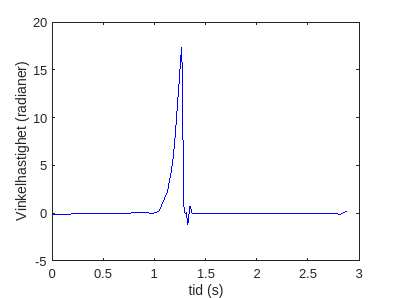


filename = 'fallande mobil.mat';
file_type = filename(end-2:end);
if file_type == "csv"
    data = readtable(filename);
    av_y = data{:,3};
else
    data = load(filename);
    av_y = data.AngularVelocity.(2)(300:end);
end 

time = linspace(0, length(av_y)/100, length(av_y));



plot(time, av_y, Color="blue", LineStyle="-");
xlabel("tid (s)");
ylabel("Vinkelhastighet (radianer)");


rads_max = max(av_y)

rads_max = 17.3282


% telefonens specs
massa = 0.151; %kg
fall_distans = 0.069 / 2; % meter
bredd = 0.0082; % meter
djupet = 0.157; % meter

g = 9.82;
I_y = (2*massa*g*fall_distans) / power(rads_max, 2);
I_p  = I_y + 2 * massa * power(bredd, 2)

I_p = 3.6105e-04


I_t = (massa/12) * (power(fall_distans*2, 2) - power(bredd, 2))

I_t = 5.9063e-05


procentuell_skillnad = (I_t / I_p)

procentuell_skillnad = 0.1636